clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 1/16*25.4 %mm

diameter =        1.5875


height = 1/32*25.4 %mm

height =       0.79375


Br_max = 14800*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;

% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02102024_D101N52_z12mm\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Adjust the location for the magnet
loc = location + [0, 0, 12];

01312024

calculate magnetic field strengths of other magnets - find combination with largets magnetic field strength 

Redo measurements closer to sensor (maybe try n52 right away)

Use smallest magnet "reasonably" detecable at 2 cm. (just measure all of them at 2cm)

    Use strongest magnet, play with z-distance, decreae

Try fitting with center 4 sensors only

% Create a cell array to store all rows
all_sen = cell(length(data_matrix), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(data_matrix)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[ 0.07554 -0.017505 -0.033154]}    {[  0.09861 -0.044865 -0.13482]}    {[   0.01686 -0.07545 -0.24089]}    {[   -0.10353 -0.05769 -0.16405]}    {[   0.07446 0.01683 -0.032815]}    {[  0.10131 0.05061 -0.12945]}    {[  0.018195 0.077775 -0.25304]}    {[ -0.10325 0.057555 -0.16536]}    {[  0.05049 0.03546 -0.016311]}    {[ 0.054765 0.079995 -0.05854]}    {[  0.00603 0.11431 -0.098663]}    {[ -0.05259 0.086625 -0.064348]}    {[ 0.022815 0.030465 0.0008954]}    {[0.01989 0.049875 -0.0097526]}    {[ 0.001155 0.063225 -0.017182]}    {[-0.02175 0.054945 -0.0076714]}
    {[0.072015 -0.023865 -0.029088]}    {[    0.0885 -0.06069 -0.11841]}    {[   0.01701 -0.09747 -0.21095]}    {[   -0.091695 -0.0732 -0.14075]}    {[   0.0783 0.008805 -0.038454]}    {[  0.11034 0.03012 -0.14254]}    {[  0.020145 0.044745 -0.27815]}    {[  -0.11047 0.03375 -0.18099]}    {[  0.05658 0.035325 -0.02132]}    {[    0.06648 0.081 -0.077585]}    {[   0.00768 0.12007 -0.12765]}    {[-0.06

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =      0.084513    -0.043207     -0.86887
     0.070375    -0.044748     -0.86592
     0.049329    -0.069574     -0.86868
       0.0345    -0.072374     -0.85744
     0.018235    -0.060904     -0.85565
    -0.021406    -0.042618     -0.85972
     0.096712    -0.068834     -0.86322
     0.083952    -0.072432      -0.8648
     0.073741    -0.070849     -0.85166
     0.049978    -0.071432     -0.85329


multiloc = multipreds(:,4:6)

multiloc =       -3.1107      -4.2817       10.501
      -3.0359      -3.2562       10.468
       -2.933       -2.147       10.477
      -2.8647      -1.1323       10.411
      -2.7715     -0.19189       10.406
      -2.5986       0.7396       10.402
      -2.1397       -4.184       10.501
      -2.0836      -3.1345       10.505
      -2.0389      -2.1286       10.429
      -1.9444      -1.1344       10.433


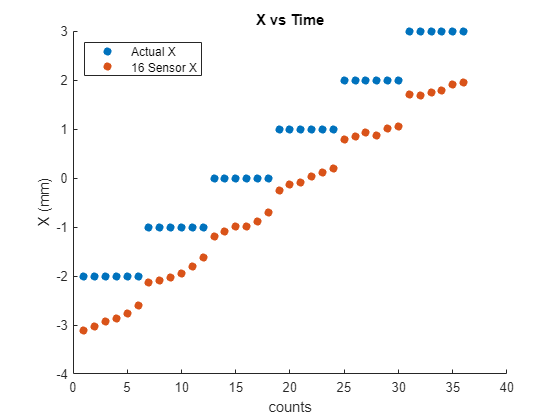

scatter(1:length(multiloc),loc(:,1), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

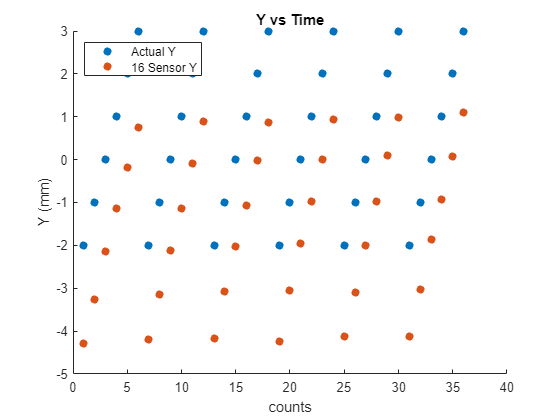

scatter(1:length(multiloc),loc(:,2), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%lim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((multiloc-r0).^2, 2));

r02 = [location(1,1) location(1,2) location(1,3)];
zi2 = sqrt(sum((location-r02).^2, 2));

SSR = sum((zi2 - testx).^2)

SSR =        1.5816


SST = sum((zi2 - mean(testx)).^2)

SST =        101.82


R2 = 1 - SSR/SST

R2 =       0.98447


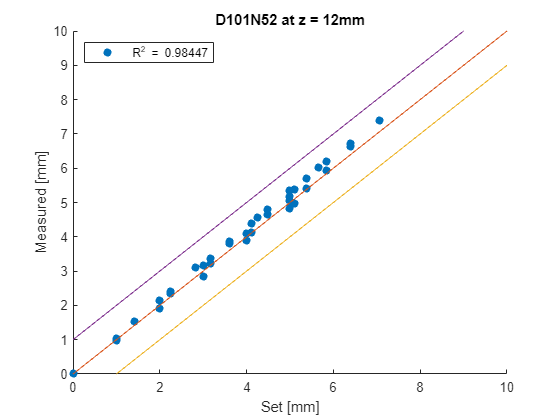


scatter(zi2, testx, 'filled')
hold on;
plot(0:10, 0:10)
plot(0:10, -1:9)
plot(0:10, 1:11)
ylim([0 10])
xlabel("Set [mm]")
ylabel('Measured [mm]')
title('D101N52 at z = 12mm')
legend(['R^2 = ', num2str(R2)], Location = 'northwest')
hold off;

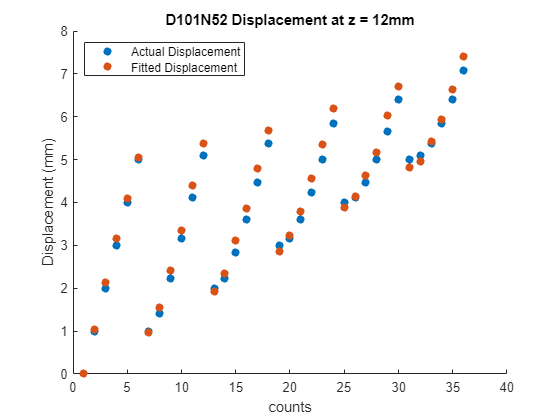


scatter(1:length(zi2), zi2, 'filled')
hold on;
scatter(1:length(testx), testx, 'filled')
title('D101N52 Displacement at z = 12mm')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

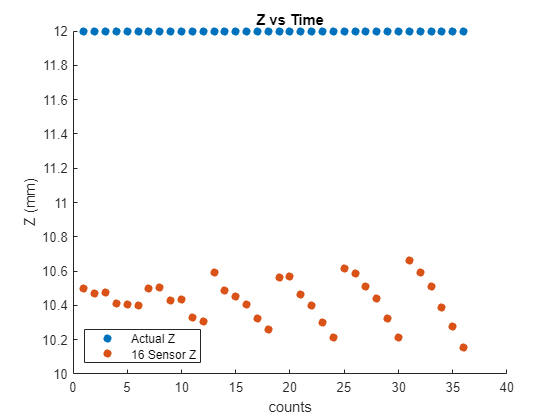

scatter(1:length(multiloc),loc(:,3), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([31,33])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

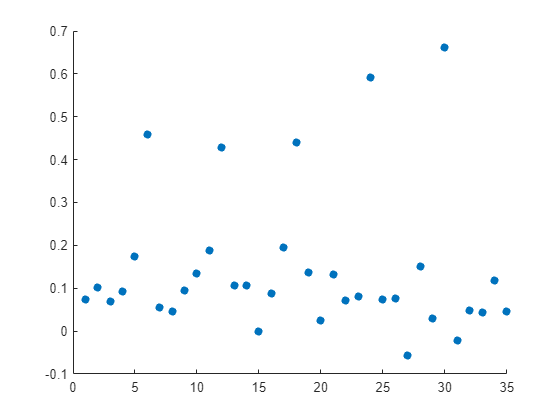

test = diff(multiloc(:,1));
scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -22]

multidisp =       -1.1107      -2.2817      -11.499
      -1.0359      -1.2562      -11.532
     -0.93303     -0.14698      -11.523
      -0.8647      0.86771      -11.589
     -0.77153       1.8081      -11.594
     -0.59856       2.7396      -11.598
     -0.13969       -2.184      -11.499
    -0.083574      -1.1345      -11.495
    -0.038893     -0.12859      -11.571
     0.055566      0.86565      -11.567


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =        11.776
       11.647
       11.562
       11.653
        11.76
       11.932
       11.706
       11.551
       11.572
       11.599



disp = [4.98 5.08 5.35 5.78 6.34 7.01 5.08 5.18 5.45 5.9 6.46 7.12 5.37 5.47 5.74 6.13 6.66 7.3 5.81 5.91 6.15 6.55 7.05 7.67 6.41 6.47 6.70 7.05 7.55 8.11 7.06 7.13 7.34 7.67 8.1 8.65]'

disp =          4.98
         5.08
         5.35
         5.78
         6.34
         7.01
         5.08
         5.18
         5.45
          5.9


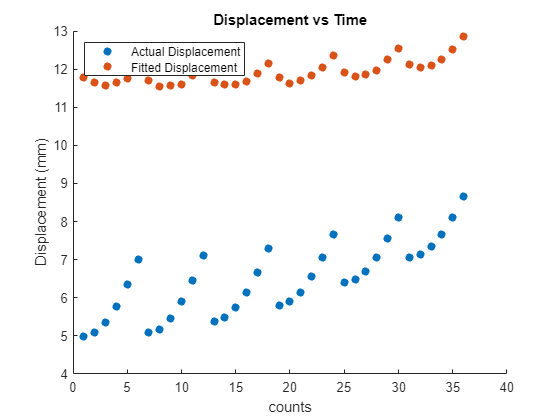


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end